# **Script pour charger et comparer des profils EMG à partir de fichiers .mat sauvegardés**

clear;
clc;

% Définir le nombre de fichiers à comparer
nb_files = 2;
colors = {'k', 'r', 'b'}; % couleurs pour les différents fichiers
linestyles = {'-', '-', '-'}; % styles de ligne

% Structures pour stocker les données chargées
all_data = cell(nb_files, 1);
file_names = cell(nb_files, 1);

% Charger les trois fichiers .mat
for i = 1:nb_files
    fprintf('\nSélection du fichier %d/%d\n', i, nb_files);
    [filename, pathname] = uigetfile('*.mat', sprintf('Sélectionnez le fichier %d de données EMG', i));
    if isequal(filename, 0) || isequal(pathname, 0)
        warning('Fichier %d non sélectionné. Seuls %d fichiers seront comparés.', i, i-1);
        nb_files = i-1;
        break;
    end
    
    % Charger les données
    loaded_data = load(fullfile(pathname, filename));
    fprintf('Données chargées à partir du fichier: %s\n', filename);
    
    % Vérifier la structure des données
    if ~isfield(loaded_data, 'data_to_save')
        error('Le fichier %s ne contient pas la structure de données attendue (data_to_save)', filename);
    end
    
    % Stocker les données et le nom du fichier
    all_data{i} = loaded_data.data_to_save;
    [~, name, ~] = fileparts(filename);
    file_names{i} = name;
end


Sélection du fichier 1/2


Données chargées à partir du fichier: average_emg_profile_PREOP.mat



Sélection du fichier 2/2


Données chargées à partir du fichier: average_emg_profile_POSTOP.mat



% Demander à l'utilisateur des noms plus descriptifs pour chaque fichier
for i = 1:nb_files
    default_name = file_names{i};
    new_name = input(sprintf('Entrez un nom descriptif pour %s (appuyez sur Enter pour conserver "%s") : ', default_name, default_name), 's');
    if ~isempty(new_name)
        file_names{i} = new_name;
    end
end

% Trouver le nombre de muscles maximum et vérifier la compatibilité
nb_muscles = 0;
for i = 1:nb_files
    data = all_data{i};
    if isfield(data, 'muscles_R')
        current_nb = length(data.muscles_R);
    elseif isfield(data, 'muscles_L')
        current_nb = length(data.muscles_L);
    else
        error('Impossible de déterminer le nombre de muscles dans le fichier %d', i);
    end
    
    if i == 1
        nb_muscles = current_nb;
    elseif current_nb ~= nb_muscles
        warning('Le nombre de muscles diffère entre les fichiers. Utilisation du nombre minimum.');
        nb_muscles = min(nb_muscles, current_nb);
    end
end

% Collecter les noms des muscles de tous les fichiers
all_muscles_R = cell(nb_files, nb_muscles);
all_muscles_L = cell(nb_files, nb_muscles);

for i = 1:nb_files
    data = all_data{i};
    if isfield(data, 'muscles_R')
        for m = 1:nb_muscles
            all_muscles_R{i, m} = data.muscles_R{m};
        end
    end
    if isfield(data, 'muscles_L')
        for m = 1:nb_muscles
            all_muscles_L{i, m} = data.muscles_L{m};
        end
    end
end

% Déterminer quelles données afficher pour chaque fichier
display_options = zeros(nb_files, 1);
display_right = false(nb_files, 1);
display_left = false(nb_files, 1);
display_combined = false(nb_files, 1);

for i = 1:nb_files
    data = all_data{i};
    display_options(i) = data.display_option;
    
    % Déterminer les options d'affichage en fonction de l'option de sauvegarde
    display_right(i) = isfield(data, 'right') && (display_options(i) == 1 || display_options(i) == 3 || display_options(i) == 4);
    display_left(i) = isfield(data, 'left') && (display_options(i) == 2 || display_options(i) == 3 || display_options(i) == 4);
    display_combined(i) = isfield(data, 'combined') && display_options(i) == 5;
end

% Demander à l'utilisateur quelle source de données utiliser pour chaque fichier
fprintf('\n===== Sélection des données à afficher pour chaque fichier =====\n');


===== Sélection des données à afficher pour chaque fichier =====


data_source = zeros(nb_files, 1);

for i = 1:nb_files
    options = {};
    opt_count = 0;
    
    if display_right(i)
        opt_count = opt_count + 1;
        options{opt_count} = 'Droite';
    end
    if display_left(i)
        opt_count = opt_count + 1;
        options{opt_count} = 'Gauche';
    end
    if display_combined(i)
        opt_count = opt_count + 1;
        options{opt_count} = 'Combinée';
    end
    
    fprintf('Pour le fichier %s, choisissez la source de données:\n', file_names{i});
    for j = 1:length(options)
        fprintf('%d. %s\n', j, options{j});
    end
    
    selected = input(sprintf('Votre choix (1-%d) : ', length(options)));
    if selected < 1 || selected > length(options)
        error('Choix non valide');
    end
    
    % Convertir le choix en type de données (1=right, 2=left, 3=combined)
    selected_option = options{selected};
    if strcmp(selected_option, 'Droite')
        data_source(i) = 1;
    elseif strcmp(selected_option, 'Gauche')
        data_source(i) = 2;
    else % Combinée
        data_source(i) = 3;
    end
end

Pour le fichier PREOP, choisissez la source de données:


1. Combinée


Pour le fichier POSTOP, choisissez la source de données:


1. Combinée


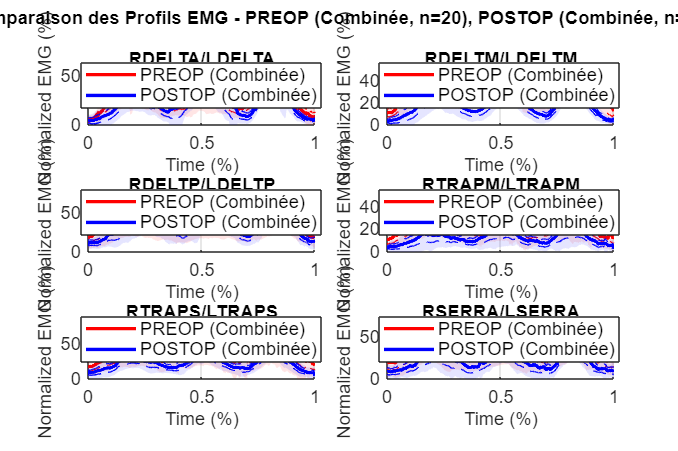


% Créer la figure
figure('Name', 'Comparaison des Profils EMG', 'Color', 'white', 'Position', [100, 100, 1200, 800]);

% Pour chaque muscle, tracer les données des trois fichiers
for m = 1:nb_muscles
    subplot(ceil(nb_muscles/2), 2, m);
    hold on;
    
    % Pour créer des handles pour la légende
    legend_handles = [];
    legend_labels = {};
    
    % Déterminer le sous-titre du graphique
    subplot_titles = cell(nb_files, 1);
    for i = 1:nb_files
        data = all_data{i};
        if data_source(i) == 1 && isfield(data, 'muscles_R')
            subplot_titles{i} = data.muscles_R{m};
        elseif data_source(i) == 2 && isfield(data, 'muscles_L')
            subplot_titles{i} = data.muscles_L{m};
        elseif data_source(i) == 3
            if isfield(data, 'muscles_R') && isfield(data, 'muscles_L')
                if isequal(data.muscles_R{m}, data.muscles_L{m})
                    subplot_titles{i} = data.muscles_R{m};
                else
                    subplot_titles{i} = [data.muscles_R{m} '/' data.muscles_L{m}];
                end
            elseif isfield(data, 'muscles_R')
                subplot_titles{i} = data.muscles_R{m};
            elseif isfield(data, 'muscles_L')
                subplot_titles{i} = data.muscles_L{m};
            end
        end
    end
    
    % Utiliser un titre unique si tous les titres sont identiques
    unique_titles = unique(subplot_titles);
    if length(unique_titles) == 1
        subplot_title = unique_titles{1};
    else
        subplot_title = sprintf('Muscle %d', m);
    end
    
    % Pour chaque fichier, tracer les données correspondantes
    for i = 1:nb_files
        data = all_data{i};
        time_vector = data.time;
        
        % Sélectionner les données selon la source spécifiée
        if data_source(i) == 1 && isfield(data, 'right') % Droite
            source_data = data.right;
            source_name = 'Droite';
        elseif data_source(i) == 2 && isfield(data, 'left') % Gauche
            source_data = data.left;
            source_name = 'Gauche';
        elseif data_source(i) == 3 && isfield(data, 'combined') % Combinée
            source_data = data.combined;
            source_name = 'Combinée';
        else
            warning('Données non disponibles pour le fichier %d, muscle %d', i, m);
            continue;
        end
        
        % Extraire correctement les données selon les dimensions
        if size(source_data.mean, 1) == nb_muscles
            mean_data = source_data.mean(m, :);
            ci_upper = source_data.ci_upper(m, :);
            ci_lower = source_data.ci_lower(m, :);
            std_data = source_data.std(m, :);
        else
            % Si les dimensions sont inversées
            mean_data = source_data.mean(:, m)';
            ci_upper = source_data.ci_upper(:, m)';
            ci_lower = source_data.ci_lower(:, m)';
            std_data = source_data.std(:, m)';
        end
        
        % Vérification des dimensions pour le tracé
        if length(time_vector) ~= length(mean_data)
            warning('Dimensions incompatibles pour le tracé: time_vector length = %d, mean_data length = %d', ...
                   length(time_vector), length(mean_data));
            continue;
        end
        
        % Tracé de la ligne moyenne
        h_line = plot(time_vector, mean_data, [colors{i}, linestyles{i}], 'LineWidth', 2);
        legend_handles = [legend_handles, h_line];
        legend_labels{end+1} = sprintf('%s (%s)', file_names{i}, source_name);
        
        % Tracé de l'écart-type avec fill
        std_upper = mean_data + std_data;
        std_lower = mean_data - std_data;
        h_fill = fill([time_vector, fliplr(time_vector)], ...
                     [std_upper, fliplr(std_lower)], ...
                     colors{i}, 'EdgeColor', 'none', 'FaceAlpha', 0.1);
        
        % Tracé de l'IC95 en pointillé
        h_ci = plot(time_vector, ci_upper, [colors{i}, '--'], 'LineWidth', 0.5);
        plot(time_vector, ci_lower, [colors{i}, '--'], 'LineWidth', 0.5);
    end
    
    % Création de la légende avec tous les éléments
    if ~isempty(legend_handles)
        legend(legend_handles, legend_labels, 'Location', 'best', 'FontSize', 8);
    end
    
    % Définition du titre du sous-graphique
    title(subplot_title, 'FontWeight', 'bold');
    
    % Axes et grille
    xlabel('Time (%)');
    ylabel('Normalized EMG (%)');
    
    % Trouver les limites communes pour l'axe x
    x_min = Inf;
    x_max = -Inf;
    for i = 1:nb_files
        time_vector = all_data{i}.time;
        x_min = min(x_min, min(time_vector));
        x_max = max(x_max, max(time_vector));
    end
    xlim([x_min, x_max]);
    
    % Collecter toutes les données pour déterminer les limites de l'axe y
    y_data = [];
    for i = 1:nb_files
        data = all_data{i};
        
        if data_source(i) == 1 && isfield(data, 'right') && isfield(data.right, 'ci_upper')
            if size(data.right.ci_upper, 1) == nb_muscles
                y_data = [y_data; data.right.ci_upper(m, :)];
            else
                y_data = [y_data; data.right.ci_upper(:, m)'];
            end
        elseif data_source(i) == 2 && isfield(data, 'left') && isfield(data.left, 'ci_upper')
            if size(data.left.ci_upper, 1) == nb_muscles
                y_data = [y_data; data.left.ci_upper(m, :)];
            else
                y_data = [y_data; data.left.ci_upper(:, m)'];
            end
        elseif data_source(i) == 3 && isfield(data, 'combined') && isfield(data.combined, 'ci_upper')
            if size(data.combined.ci_upper, 1) == nb_muscles
                y_data = [y_data; data.combined.ci_upper(m, :)];
            else
                y_data = [y_data; data.combined.ci_upper(:, m)'];
            end
        end
    end
    
    if ~isempty(y_data)
        y_max = max(y_data(:));
        ylim([0, y_max * 1.1]);
    end
    
    grid on;
end

% Préparation du titre global
title_str = 'Comparaison des Profils EMG';

% Ajouter des informations sur les fichiers au titre
file_info = '';
for i = 1:nb_files
    data = all_data{i};
    n_subjects = 0;
    source_name = '';
    
    if data_source(i) == 1 && isfield(data, 'right') && isfield(data.right, 'n')
        n_subjects = data.right.n;
        source_name = 'Droite';
    elseif data_source(i) == 2 && isfield(data, 'left') && isfield(data.left, 'n')
        n_subjects = data.left.n;
        source_name = 'Gauche';
    elseif data_source(i) == 3 && isfield(data, 'combined') && isfield(data.combined, 'n')
        n_subjects = data.combined.n;
        source_name = 'Combinée';
    end
    
    if i > 1
        file_info = [file_info, ', '];
    end
    file_info = [file_info, sprintf('%s (%s, n=%d)', file_names{i}, source_name, n_subjects)];
end

title_str = [title_str, ' - ', file_info];

% Ajout du titre global
sgtitle(title_str, 'FontWeight', 'bold', 'FontSize', 12);

% Ajustement de la mise en page
set(gcf, 'Color', 'white');
set(findall(gcf, '-property', 'FontSize'), 'FontSize', 11);


% Afficher des informations sur les fichiers chargés
fprintf('\n===== Informations sur les fichiers comparés =====\n');


===== Informations sur les fichiers comparés =====


for i = 1:nb_files
    data = all_data{i};
    source_type = '';
    n_subjects = 0;
    
    if data_source(i) == 1 && isfield(data, 'right')
        source_type = 'Droite';
        n_subjects = data.right.n;
    elseif data_source(i) == 2 && isfield(data, 'left')
        source_type = 'Gauche';
        n_subjects = data.left.n;
    elseif data_source(i) == 3 && isfield(data, 'combined')
        source_type = 'Combinée';
        n_subjects = data.combined.n;
    end
    
    fprintf('Fichier %d: %s\n', i, file_names{i});
    fprintf('  - Source: %s (n=%d)\n', source_type, n_subjects);
    if isfield(data, 'date')
        fprintf('  - Date de sauvegarde: %s\n', data.date);
    end
    
    % Afficher les sujets sélectionnés
    if data_source(i) == 1 && isfield(data, 'selected_subjects_R')
        fprintf('  - Sujets: %s\n', mat2str(data.selected_subjects_R));
    elseif data_source(i) == 2 && isfield(data, 'selected_subjects_L')
        fprintf('  - Sujets: %s\n', mat2str(data.selected_subjects_L));
    elseif data_source(i) == 3
        % Pour les données combinées, afficher les deux ensembles de sujets
        if isfield(data, 'selected_subjects_R') && isfield(data, 'selected_subjects_L')
            fprintf('  - Sujets droite: %s\n', mat2str(data.selected_subjects_R));
            fprintf('  - Sujets gauche: %s\n', mat2str(data.selected_subjects_L));
        end
    end
    fprintf('\n');
end

Fichier 1: PREOP


  - Source: Combinée (n=20)


  - Date de sauvegarde: 23-May-2025 13:47:38


  - Sujets droite: [1 3 4 6 7 9 11 12 33 37]


  - Sujets gauche: [10 18 19 20 22 23 26 28 31 32]


Fichier 2: POSTOP


  - Source: Combinée (n=20)


  - Date de sauvegarde: 23-May-2025 13:44:41


  - Sujets droite: [1 3 4 6 7 9 11 12 33 37]


  - Sujets gauche: [10 18 19 20 22 23 26 28 31 32]
